clear all, close all, clc
m = 1; M = 5; L = 2; g = -10; d = 1;
b = -1; % Pendulum up (b=1)

A = [0 1 0 0;
    0 -d/M b*m*g/M 0;
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; b*1/(M*L)];
C = [1 0 0 0];  

D = zeros(size(C,1),size(B,2));

sysC = ss(A,B,C,D);  % system with only x as its output 
sysFullOutput = ss(A,B,eye(4),D);  % Full state output

Q = eye(4);
R = 0.001

R = 1.0000e-03

L = (lqr(A',C',Q,R))';
sysKF = ss(A-L*C,[B L],eye(4),0*[B L]);  % Kalman filter estimator

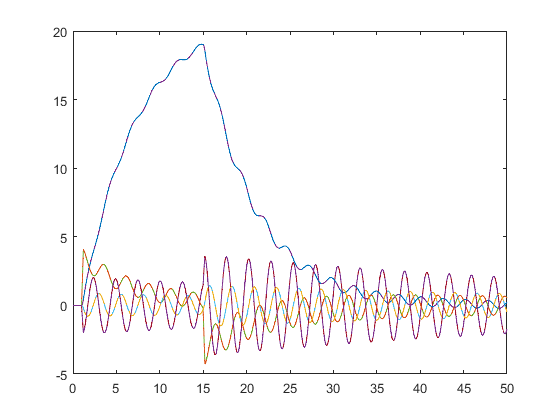

dt = .01;
t = 0:dt:50;

u = 0*t;
u(100:120) = 100;     % impulse
u(1500:1520) = -100;  % impulse

[y,t] = lsim(sysC,u,t);
[xtrue,t] = lsim(sysFullOutput,u,t);
[x_est,t] = lsim(sysKF,[u; y'],t);

plot(t,xtrue,'-',t,x_est,'--','LineWidth',1)

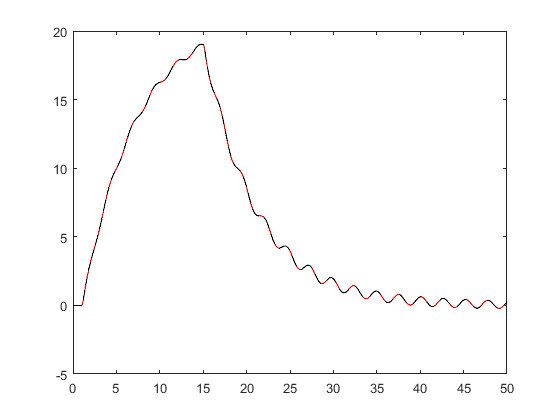


figure
plot(t,y)
hold on
plot(t,xtrue(:,1),'r')
plot(t,x_est(:,1),'k--')